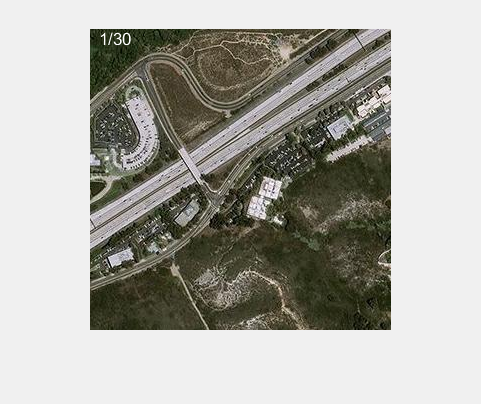

clc
clear all
close all

letter = "B";
directory = "Test Images/Snipped/"+letter+"/";
imagefiles = dir(directory);      
nfiles = length(imagefiles);    % Number of files found

% figure()
for ii=4:nfiles
   currentfilename = imagefiles(ii).name;
   currentimage = imread(directory+currentfilename);
   images{ii - 3} = currentimage;
   [~,imageNames{ii - 3},~] = fileparts(currentfilename);
   % subplot(nfiles-3, 1, ii - 3);
   % imshow(images{ii - 3});
end

neworder = randperm(length(images));
for i=1:length(images)
    images2{i} = images{neworder(i)};
end
images = images2;

% images{1} = imread("Test Images/Snipped/A/A4.jpg");
% images{2} = imread("Test Images/Snipped/A/A7.jpg");
% images{3} = imread("Test Images/Snipped/A/A15.jpg");
% images{4} = imread("Test Images/Snipped/A/A12.jpg");
% images{5} = imread("Test Images/Snipped/A/A18.jpg");

% images{1} = imread("leftoriginal.png")
% images{2} = imread("leftleft.png")

% % right = imread("leftshifted.png");
% figure()
% imshow(images{1})
% imshow(images{2})

fig = figure;
set(gcf,'Visible','on');

out = images{1};
thresh = 0.0005;
speedthresh = 0.01;
stitched = zeros(length(images),1);
stitched(1)=1;
length(images);

pltanim(out,stitched);


end_early = false;
default_points = 0.5;
for j=1:length(images)
    disp(j)
    points=default_points;
    finished = false;
    while ~finished
        confidences = zeros(length(images),3);
        for i=1:length(images)
            if stitched(i)==0
                [final_slope, final_length, final_delta_x, final_delta_y, final_confidence] = custom_sift(out, images{i}, 8, points, true);
                confidences(i,:)=[final_confidence,final_delta_x,final_delta_y];
                if confidences(i,1)>=speedthresh
                    break
                end
            end
        end
        if sum(confidences(:,1)>=thresh)~=0
            [v,ind]=max(confidences(:,1));
            disp(v)
            [out, valid] = merge_images(out, images{ind}, round(-confidences(ind,2)), round(-confidences(ind,3)));
            % imwrite(out, "Output/"+letter+"/Run3_Stitch"+sum(stitched)+"_Conf"+round(v*10000)+".jpg");
            if ~valid
                points=points+0.5
                if points>=3.5
                    finished=true;
                    end_early=true;
                end
            else
                points=default_points;
                stitched(ind)=1;
                pltanim(out,stitched);
            end
        else
            if points>=2.5
                finished=true;
                end_early=true;
            else
                points=points+0.5
                default_points=default_points+0.25
            end
        end
    end
    if end_early
        break
    end
end

     1



    0.0288



ans = 0.4960

    0.0617



ans = 0.7053

    0.0887



ans = 0.4343

    0.0862



ans = 0.2620

    0.0062



ans = 0.6348

    0.3058



ans = 0.5571

    0.0861



ans = 0.2779

    0.2355



ans = 0.3753

    0.0011



ans = 0.5036

    0.3845



ans = 0.5755

    0.0209



ans = 0.7905

    0.0379



ans = 0.7557

    0.3911



ans = 0.6432

    0.0151



ans = 1.2086

points = 1

    0.0128



ans = 1.2325

points = 1.5000

    0.0105



ans = 1.2305

points = 2

    0.0152



ans = 1.2100

points = 2.5000

    0.0152



ans = 1.2110

points = 3

sum(stitched)
imageNames(~stitched)
pltanim(out,stitched);
text(10,30,"Done!","Color",[1,1,1]);

function [] = pltanim(out, stitched)
        imshow(out);
        text(10,10,""+sum(stitched)+"/"+length(stitched),"Color",[1,1,1]);
        drawnow();
end